PARCISER - Projet 6.1 


map2 = [[0 1 2]'  [0 0 0]'  [10 10 10]'];
fmin = 10e9; fmax = 18e9; % fmin et fmax
th1 = -180; th2=180;  %angle min et max

nf = 9; nth = 5*360; %Nombre d'échantillons respectivement en angle, et en fréquence.
sigc = gpuArray(gen_synth(map2,fmin,fmax,nf,th1,th2,nth));  %Permet de faire les calculs sur le GPU, plus rapide.

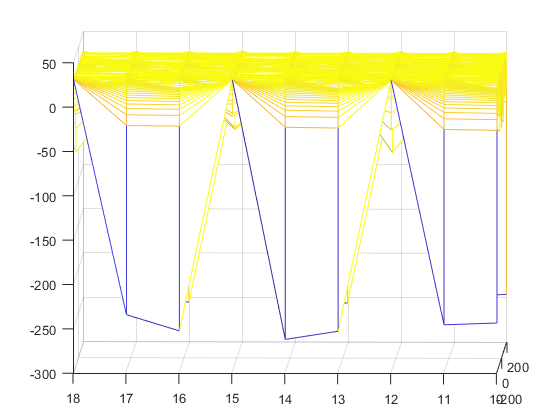

figure
mesh(linspace(th1,th2,nth),linspace(fmin/1e9,fmax/1e9,nf),20*log10(abs(sigc)))